T = readtable(['lab2_1_data.csv']);

Error using readtable (line 318)
Unable to find or open 'lab2_1_data.csv'. Check the path and filename or file permissions.

X=table2array(T);

eta=0.001;
[w,w_history,norm_history,diff]=hebbian(X,eta,'Naive');
scatter(X(1,:),X(2,:))
hold on
plotv(w,'-')
Q=X*X';
[Evec,Eval]=eig(Q);
maxeval=max(diag(Eval))
eval=diag(Eval)==maxeval;
vec=(Evec(:,eval));
plotv(vec)
hold off
figure
plot([1:length(w_history(1,:))],w_history(1,:))
figure
plot([1:length(w_history(2,:))],w_history(2,:))
figure
plot([1:length(norm_history(1,:))],norm_history(1,:))

disp('--------------------')

--------------------


[w,w_history,norm_history,diff1]=hebbian(X,eta,'Oja');

MAX IT
     5



scatter(X(1,:),X(2,:))
hold on
plotv(w,'-')
[Evec,Eval]=eig(Q);
maxeval=max(diag(Eval))

maxeval = 58.3095

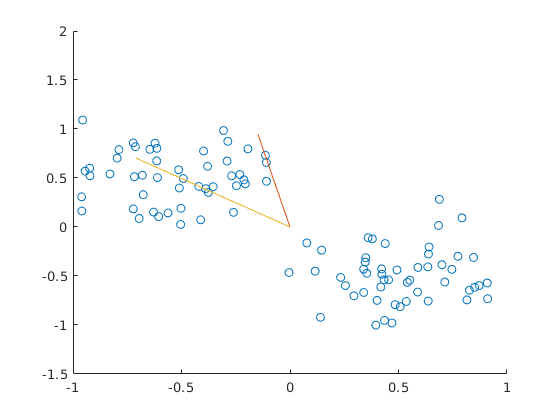

eval=find(diag(Eval)==maxeval);
vec=(Evec(:,eval));
plotv(vec(:,end))
plot(eval);
hold off

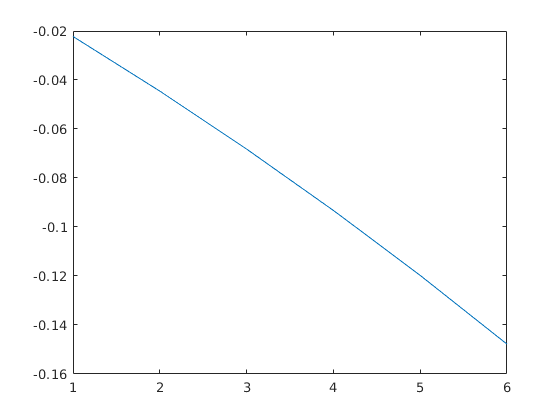

figure
plot([1:length(w_history(1,:))],w_history(1,:))

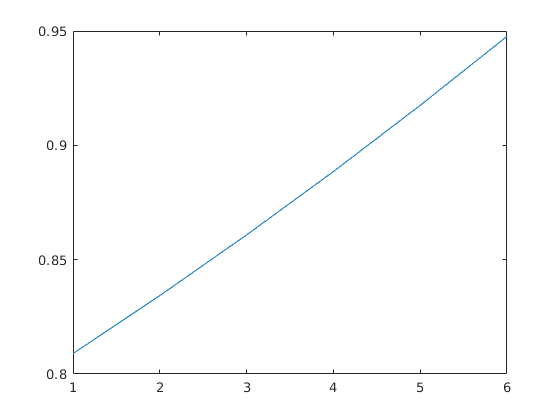

figure
plot([1:length(w_history(2,:))],w_history(2,:))

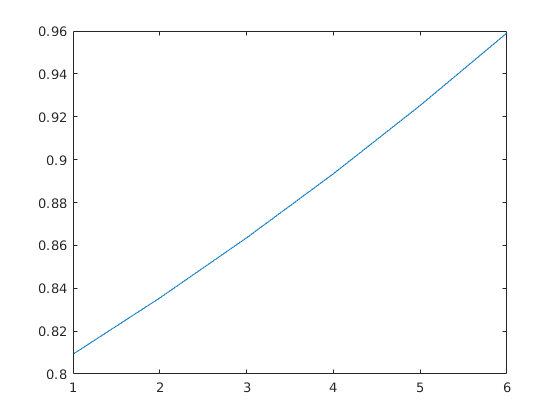

figure
plot([1:length(norm_history(1,:))],norm_history(1,:))


disp('--------------------')

--------------------


[w,w_history,norm_history,diff1]=hebbian(X,eta,'Sub_Norm');

MAX IT
    10



scatter(X(1,:),X(2,:))
hold on
plotv(w,'-')
[Evec,Eval]=eig(Q);
maxeval=max(diag(Eval))

maxeval = 58.3095

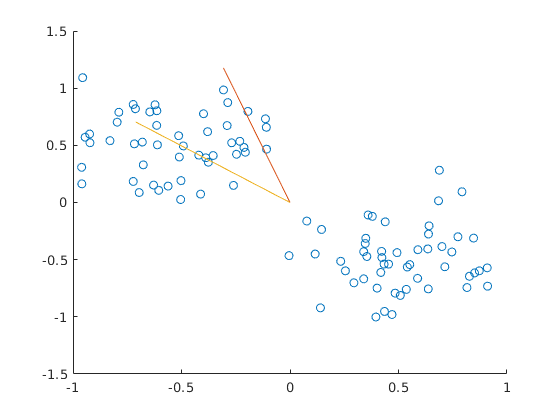

eval=find(diag(Eval)==maxeval);
vec=(Evec(:,eval));
plotv(vec(:,end))
hold off

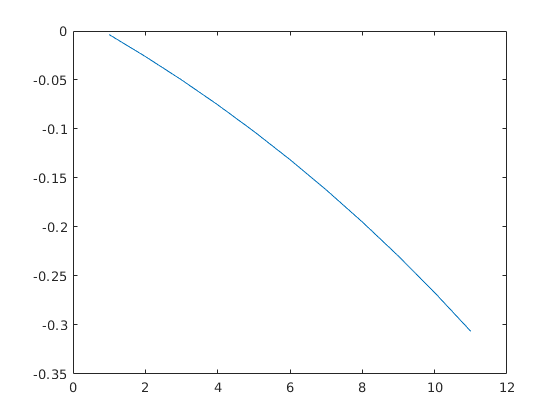

figure
plot([1:length(w_history(1,:))],w_history(1,:))

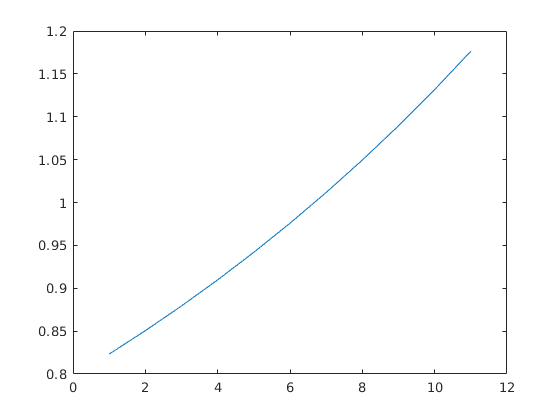

figure
plot([1:length(w_history(2,:))],w_history(2,:))

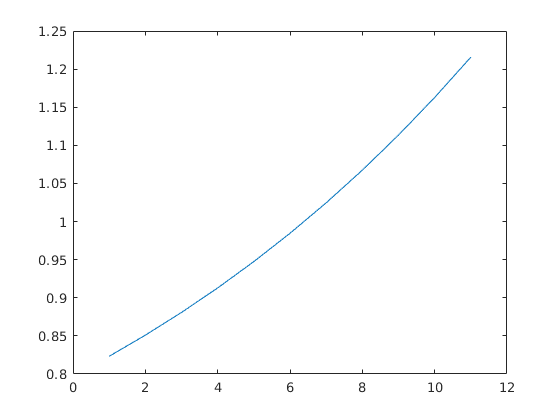

figure
plot([1:length(norm_history(1,:))],norm_history(1,:))


disp('--------------------')

--------------------


[w,w_history,norm_history,diff1]=hebbian(X,eta,'BCM');

MAX IT
     1



scatter(X(1,:),X(2,:))
hold on
plotv(w,'-')
[Evec,Eval]=eig(Q);
maxeval=max(diag(Eval))

maxeval = 58.3095

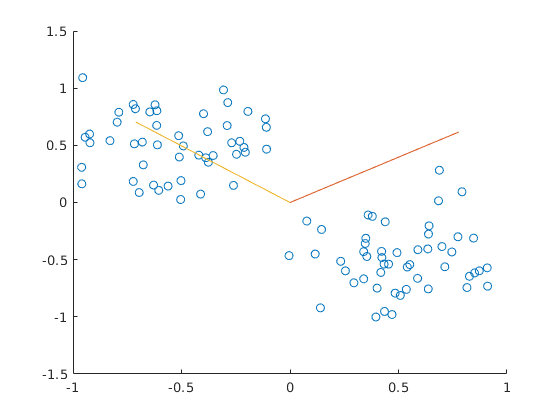

eval=find(diag(Eval)==maxeval);
vec=(Evec(:,eval));
plotv(vec(:,end))
hold off

figure
len=length(w_history(1,:))

len = 2

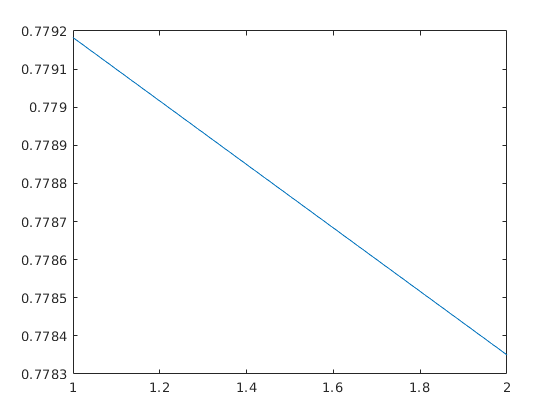

plot([1:length(w_history(1,:))],w_history(1,:))

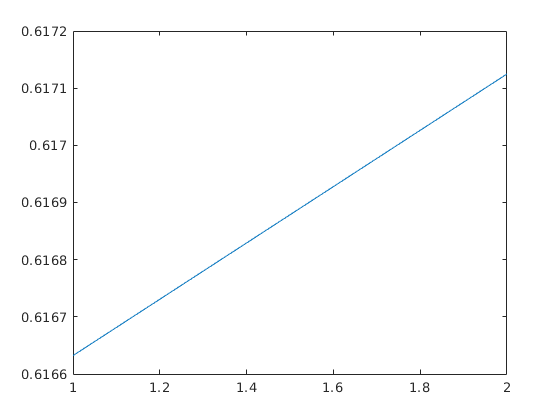

figure
plot([1:length(w_history(2,:))],w_history(2,:))

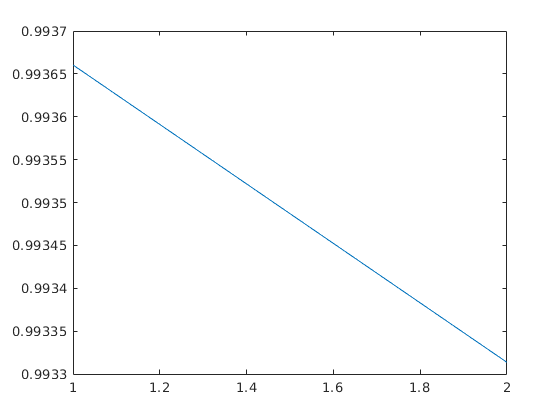

figure
plot([1:length(norm_history(1,:))],norm_history(1,:))

disp('--------------------')

--------------------


[w,w_history,norm_history,diff1]=hebbian(X,eta,'Cov');

MAX IT
     3



scatter(X(1,:),X(2,:))
hold on
plotv(w,'-')

[Evec,Eval]=eig(Q);
maxeval=max(diag(Eval))

maxeval = 58.3095

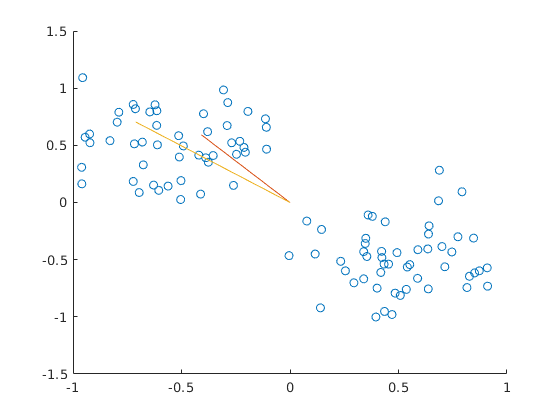

eval=find(diag(Eval)==maxeval);
vec=(Evec(:,eval));
plotv(vec(:,end))
hold off

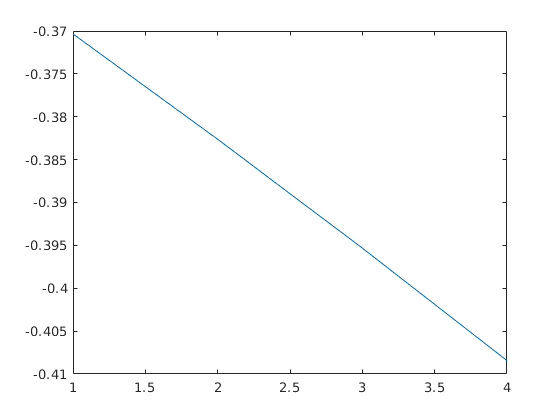

figure
plot([1:length(w_history(1,:))],w_history(1,:))

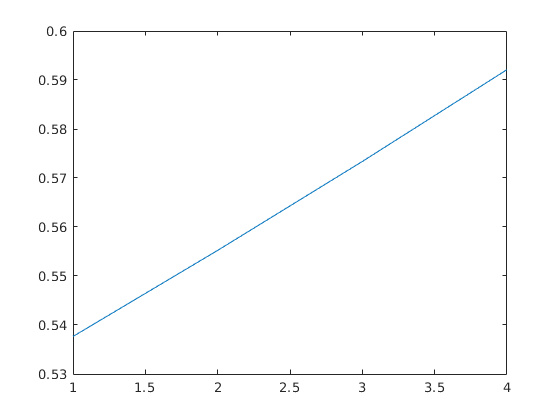

figure
plot([1:length(w_history(2,:))],w_history(2,:))

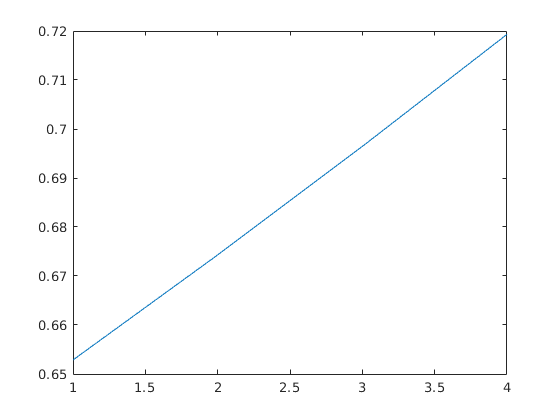

figure
plot([1:length(norm_history(1,:))],norm_history(1,:))